Separar en datos "train" (impares) y datos "validation" (pares)

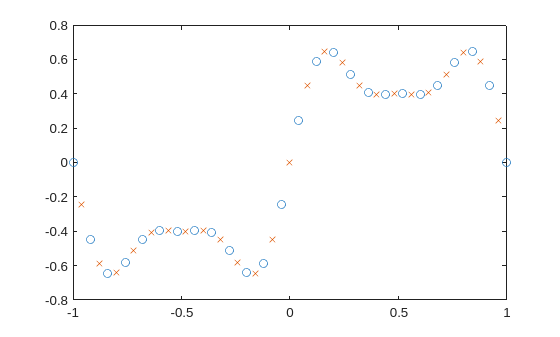

n_puntos = 51;
x = linspace(-1,1,n_puntos)';

y = 0.6*sin(pi*x) + 0.3*sin(3*pi*x) + 0.1*sin(5*pi*x);

data = [x y];

trndata = data(1:2:n_puntos,:);  % impares -> train
chkdata = data(2:2:n_puntos,:);  % pares  -> validation

figure;

plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');

Crear FIS

numMFs  = 5;
mfType  = 'gbellmf';     % campana generalizada

fismat = genfis1(trndata, numMFs, mfType);

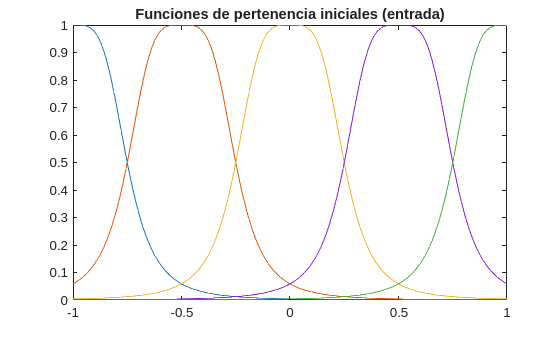

figure;
[xmf, ymf] = plotmf(fismat,'input',1);
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');

Entrenar FIS con ANFIS

numEpochs = 40;

[fismat1, trnErr, ss, fismat2, chkErr] = anfis(trndata, fismat, numEpochs, NaN, chkdata);


ANFIS info:
	Number of nodes: 24
	Number of linear parameters: 10
	Number of nonlinear parameters: 15
	Total number of parameters: 25
	Number of training data pairs: 26
	Number of checking data pairs: 25
	Number of fuzzy rules: 5


Start training ANFIS ...

1 	 0.0601596 	 0.058193
2 	 0.0571745 	 0.0553133
3 	 0.0541812 	 0.0524169
4 	 0.0511445 	 0.0494663
Step size increases to 0.011000 after epoch 5.
5 	 0.0480347 	 0.0464298
6 	 0.0448293 	 0.0432847
7 	 0.0411744 	 0.0396855
8 	 0.0373731 	 0.0359407
Step size increases to 0.012100 after epoch 9.
9 	 0.0334245 	 0.0320729
10 	 0.0293435 	 0.0281343
11 	 0.0247583 	 0.023834
12 	 0.0202327 	 0.0197763
Step size increases to 0.013310 after epoch 13.
13 	 0.0161718 	 0.0163196
14 	 0.0134263 	 0.0140181
15 	 0.0125737 	 0.0132477
16 	 0.012536 	 0.0132533
Step size increases to 0.014641 after epoch 17.
17 	 0.0121838 	 0.0130225
18 	 0.0122131 	 0.012973
19 	 0.0121333 	 0.0129426
20 	 0.011986 	 0.012762
21 	 0.0119031 	 0.0127117

Comprobar RMSE en datos

epoch = 1:numEpochs;

trnOut = evalfis(trndata(:,1), fismat1);        % Comprobar "Train"

trnRMSE = norm(trnOut - trndata(:,2))/sqrt(length(trnOut))

trnRMSE = 0.0104


chkOut = evalfis(chkdata(:,1), fismat2);        % Comprobar "Val"

chkRMSE = norm(chkOut - chkdata(:,2))/sqrt(length(chkOut))

chkRMSE = 0.0112

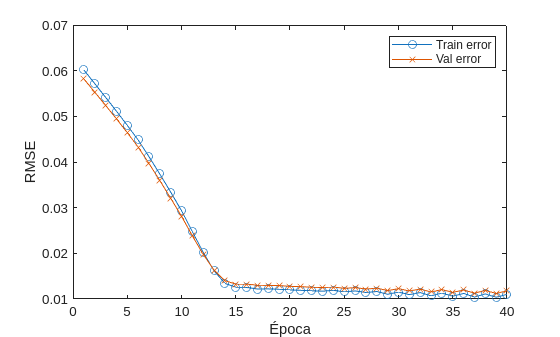


plot(epoch, trnErr, 'o-');
hold on;
plot(epoch, chkErr, 'x-');
hold off
xlabel('Época');
ylabel('RMSE');
legend('Train error','Val error');

Tamaño del Paso del Gradiente

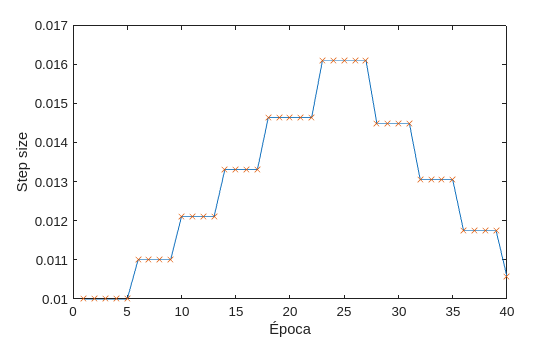

plot(epoch, ss,'-'); 
hold on;
plot(epoch, ss,'x');
hold off
xlabel('Época'); ylabel('Step size');

Funciones de Pertenencia después del entrenamiento

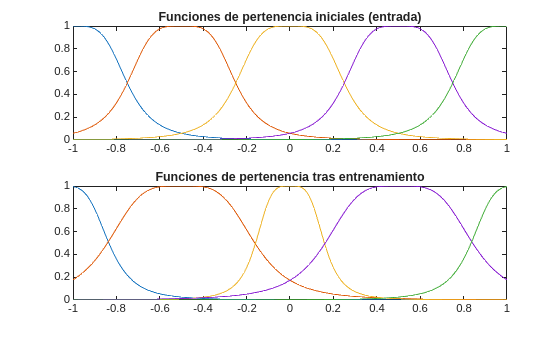

figure;
[xmf2, ymf2] = plotmf(fismat1,'input',1);
subplot(2,1,1)
plot(xmf, ymf);
title('Funciones de pertenencia iniciales (entrada)');
subplot(2,1,2)
plot(xmf2, ymf2);
title('Funciones de pertenencia tras entrenamiento');

Resultados

anfis_y = evalfis(x, fismat1);

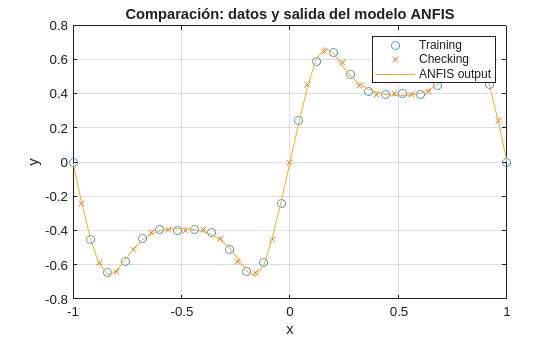


figure;
plot(trndata(:,1), trndata(:,2),'o'); hold on;
plot(chkdata(:,1), chkdata(:,2),'x');
plot(x, anfis_y,'-');
grid on;
legend('Training','Checking','ANFIS output');
xlabel('x'); ylabel('y');
title('Comparación: datos y salida del modelo ANFIS');

anfis_y_init = evalfis(x, fismat);

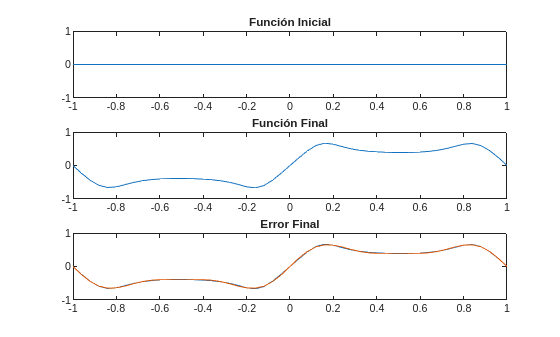


figure;
subplot(3,1,1)
plot(x, anfis_y_init,'-');
title('Función Inicial');
subplot(3,1,2)
plot(x, anfis_y,'-');
title('Función Final');
subplot(3,1,3)
plot(x, anfis_y,'-');
hold on;
plot(x, y,'-');
hold off;
title('Error Final');